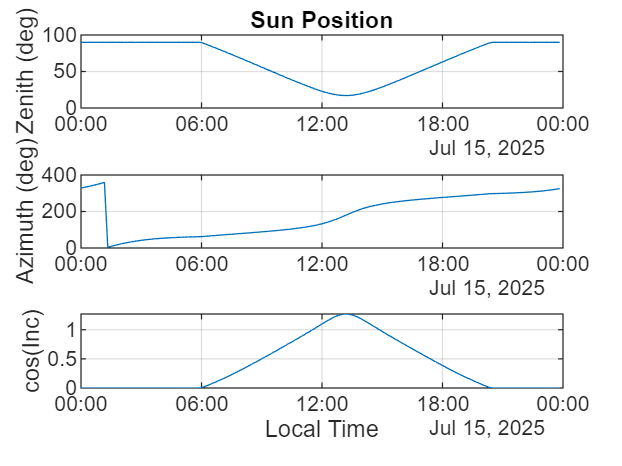

%% Solar Panel Performance Model (POA + Temp + Power)
% Computes solar geometry, POA irradiance, panel temperature, and power.

%% USER CONFIG
% Location & date/time
lat  = 38.58;              % deg  (Sacramento-ish)
lon  = -121.49;            % deg  (West negative)
tz   = -7;                 % hours offset from UTC (PDT = -7, PST = -8)
date = datetime(2025,7,15);% any day you want

% Panel & system
A_panel   = 1.90;          % m^2 panel area (e.g., ~60-cell module)
eta_ref   = 0.205;         % module efficiency at STC (25C, 1000 W/m^2)
gamma_T   = -0.0045;       % 1/°C, power temp coefficient (e.g., -0.45%/°C)
NOCT      = 45;            % °C, Nominal Operating Cell Temp (800 W/m^2, 20°C)
derate_DC = 0.96;          % wiring/mismatch/soiling DC derate
inv_eff   = 0.97;          % inverter efficiency to AC

% Mounting geometry
tilt_deg   = 25;           % panel tilt from horizontal (deg)
azim_deg   = 180;          % panel azimuth: 180 = south, 90 = east, 270 = west

% Optional: supply your own GHI (vector of W/m^2 aligned to 'tvec')
% Leave as [] to use clear-sky model.
user_GHI = [];             % e.g., csvread('ghi_series.csv')

% Time vector (local clock)
tvec = date + minutes(0:10:1440-10);   % 10-min step for 1 day

%% Solar geometry (NOAA/Cooper-style)
% Convert to solar time using Equation of Time
n = day(tvec,'dayofyear');
B = (360/365) * (n - 81);             % deg
EoT = 9.87*sind(2*B) - 7.53*cosd(B) - 1.5*sind(B); % minutes

% Local solar time (hours)
LSTM = 15*tz;                          % deg
TC = 4*(lon - LSTM) + EoT;             % minutes
LST = hour(tvec) + minute(tvec)/60 + second(tvec)/3600 + TC/60;

% Hour angle (deg), declination (deg)
H = 15*(LST - 12);                     % deg
delta = 23.45 * sind(360*(284 + n)/365);

% Solar zenith & azimuth (deg)
cosZ = sind(lat).*sind(delta) + cosd(lat).*cosd(delta).*cosd(H);
cosZ = max(cosZ, 0);                   % no sun below horizon
Z = acosd(cosZ);

sinAz = -cosd(delta).*sind(H)./sind(max(1e-6, 90-Z));
cosAz = (sind(delta) - sind(lat).*cosZ) ./ (cosd(lat).*sind(max(1e-6,90-Z)));
Az = atan2d(sinAz, cosAz);             % -180..180, 0=N, +E
Az(Az<0) = Az(Az<0) + 360;             % 0..360, 180 = south

%% Clear-sky GHI (Haurwitz) if user_GHI empty
if isempty(user_GHI)
    % Haurwitz: GHI_cs ≈ 1098 * cosZ * exp(-0.059 / max(cosZ,eps))
    cosZ_eff = max(cosZ, 1e-6);
    GHI = 1098 .* cosZ_eff .* exp(-0.059 ./ cosZ_eff);
    GHI(Z>=90) = 0;
else
    GHI = user_GHI(:);
    if numel(GHI) ~= numel(tvec)
        error('Length of user_GHI must match length of tvec.');
    end
end

%% Plane-of-Array (POA) irradiance via incidence angle
tilt = tilt_deg; azm = azim_deg;
% Incidence angle formula
cosInc = sind(90-tilt).*cosZ + cosd(90-tilt).*sind(90-Z).*cosd(Az - azm);
cosInc = max(cosInc, 0);

% Simple transposition: POA ≈ GHI * (cos(inc)/max(cosZ,eps))
cosZ_eff = max(cosZ, 1e-3);
G_poa = GHI .* (cosInc ./ cosZ_eff);
G_poa(Z>=90) = 0;

%% Cell temperature (NOCT model)
% T_cell = T_amb + (NOCT - 20)/800 * G_poa
T_amb = 25 + 10*sin(2*pi*(hour(tvec)-6)/24);  % simple diurnal ambient °C
T_cell = T_amb + (NOCT - 20)/800 .* G_poa;

%% Power model (STC correction + temp)
% P_dc = G_poa*A*eta_ref * [1 + gamma_T*(T_cell - 25°C)] * derate
P_dc = G_poa .* A_panel .* eta_ref .* (1 + gamma_T*(T_cell - 25)) * derate_DC;
P_dc(P_dc<0) = 0;
P_ac = P_dc * inv_eff;

% Daily energy (kWh)
dt_hr = minutes(tvec(2)-tvec(1))/60;
E_ac_kWh = sum(P_ac)*dt_hr/1000;

%% Plots
figure('Color','w','Name','Solar Geometry');
subplot(3,1,1); plot(tvec, Z); grid on; ylabel('Zenith (deg)'); title('Sun Position');
subplot(3,1,2); plot(tvec, Az); grid on; ylabel('Azimuth (deg)');
subplot(3,1,3); plot(tvec, cosInc); grid on; ylabel('cos(Inc)'); xlabel('Local Time');

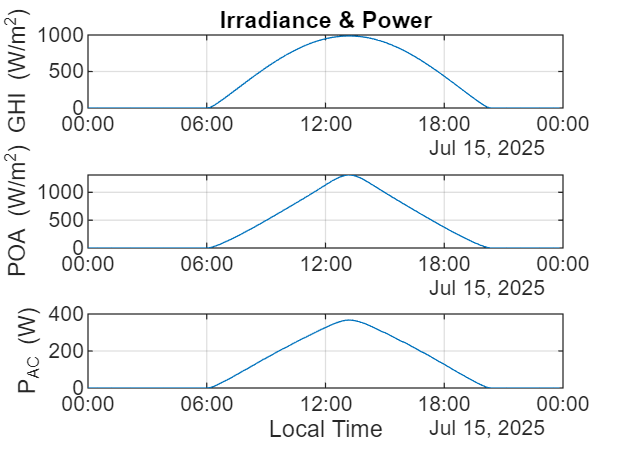


figure('Color','w','Name','Irradiance & Power');
subplot(3,1,1); plot(tvec, GHI); grid on; ylabel('GHI (W/m^2)'); title('Irradiance & Power');
subplot(3,1,2); plot(tvec, G_poa); grid on; ylabel('POA (W/m^2)');
subplot(3,1,3); plot(tvec, P_ac); grid on; ylabel('P_{AC} (W)'); xlabel('Local Time');


fprintf('\n=== Solar Summary (%s, lat %.2f, lon %.2f) ===\n', datestr(date), lat, lon);


=== Solar Summary (15-Jul-2025, lat 38.58, lon -121.49) ===


fprintf('Panel tilt %g°, azim %g°  -> Daily Energy ~ %.2f kWh\n', tilt_deg, azim_deg, E_ac_kWh);

Panel tilt 25°, azim 180°  -> Daily Energy ~ 2.78 kWh


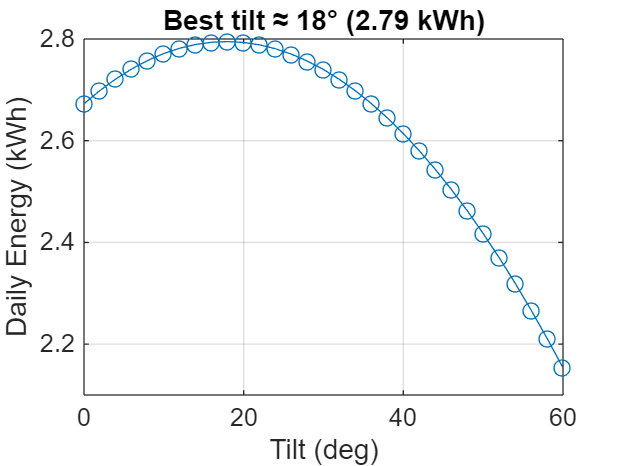


%% Tilt sweep (quick optimization for this day)
tilt_grid = 0:2:60;
E_kWh = zeros(size(tilt_grid));
for i = 1:numel(tilt_grid)
    tilt_i = tilt_grid(i);
    cosInc_i = sind(90-tilt_i).*cosZ + cosd(90-tilt_i).*sind(90-Z).*cosd(Az - azm);
    cosInc_i = max(cosInc_i, 0);
    G_poa_i = GHI .* (cosInc_i ./ cosZ_eff);
    G_poa_i(Z>=90) = 0;
    T_cell_i = T_amb + (NOCT - 20)/800 .* G_poa_i;
    P_dc_i = G_poa_i .* A_panel .* eta_ref .* (1 + gamma_T*(T_cell_i - 25)) * derate_DC;
    P_dc_i(P_dc_i<0) = 0;
    P_ac_i = P_dc_i * inv_eff;
    E_kWh(i) = sum(P_ac_i)*dt_hr/1000;
end
[~,idxBest] = max(E_kWh);

figure('Color','w','Name','Tilt Sweep');
plot(tilt_grid, E_kWh, 'o-'); grid on
xlabel('Tilt (deg)'); ylabel('Daily Energy (kWh)');
title(sprintf('Best tilt ≈ %d° (%.2f kWh)', tilt_grid(idxBest), E_kWh(idxBest)));